# Illustrate sensor aliasing using a monochrome sensor

When the acuity of the lens exceeds the sampling rate of the sensor, aliasing patterns emerge. These are low frequency patterns in the sensor response that are caused by the high frequency patterns in the original image but under-sampled by the sensor.

To protect against aliasing, you can use a lens that does not pass the high frequency terms.

The aliasing artifacts illustrated here are for a monochrome sensor. When the same problem arises from a color CFA, the artifacts emerge as unwanted colors (chromatic aliasing).

Copyright Imageval Consulting, LLC, 2016

ieInit

## Set up a sweep frequency with a high quality lens

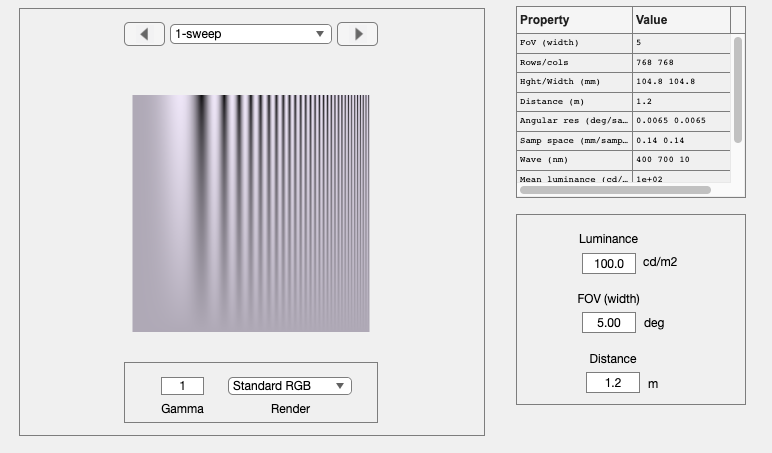

fov = 5;
scene = sceneCreate('sweep frequency',768,30);
scene = sceneSet(scene,'fov',fov);
sceneWindow(scene);

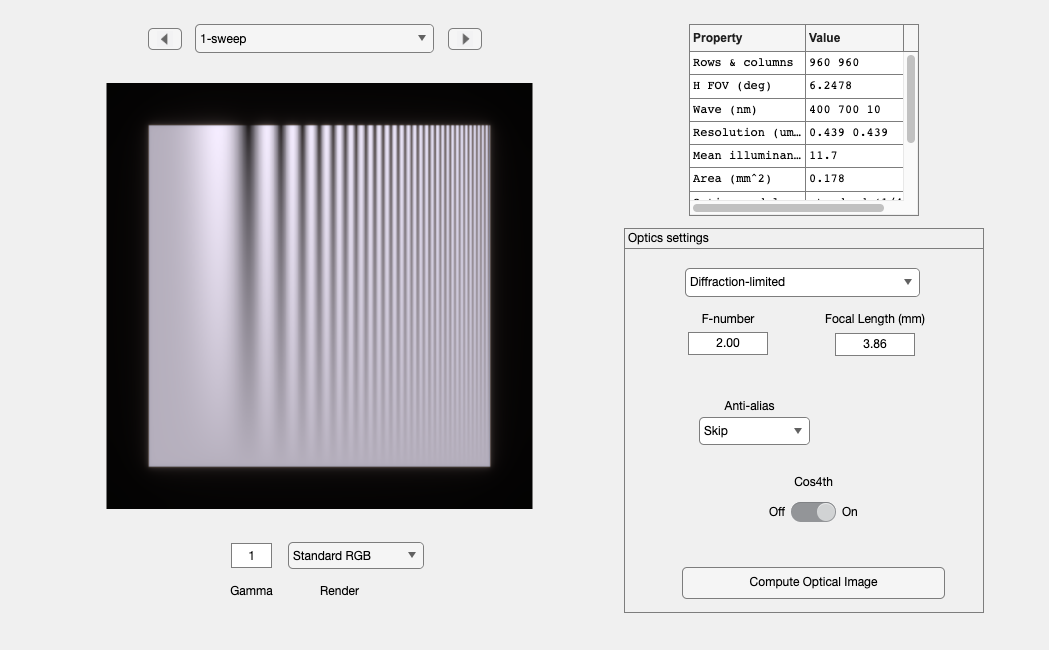


% Set up a high acuity lens
oi = oiCreate('diffraction limited');
oi = oiSet(oi,'optics fnumber', 2);
oi = oiCompute(oi,scene);
oiWindow(oi);

## We use a small pixel size and see the scene come through correctly

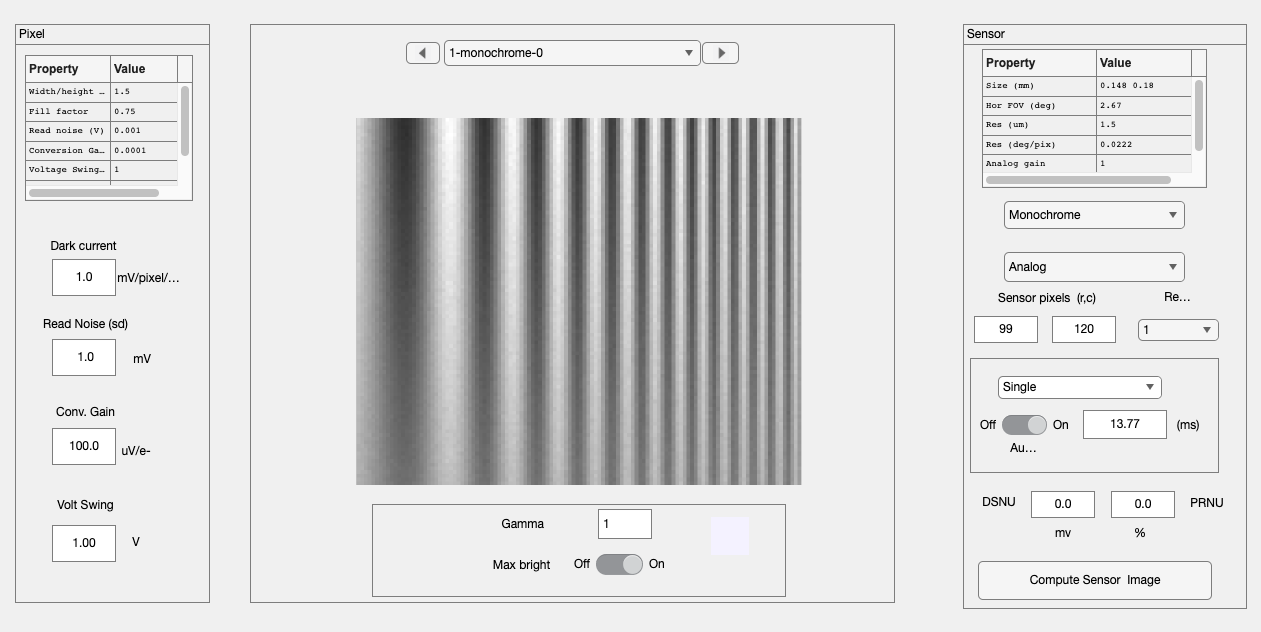

sensor = sensorCreate('monochrome');
sensor = sensorSetSizeToFOV(sensor,fov,oi);

% Set a two micron pixel
sensor = sensorSet(sensor,'pixel size constant fill factor',1.5e-6);
sensor = sensorCompute(sensor,oi);
sensorWindow(sensor);

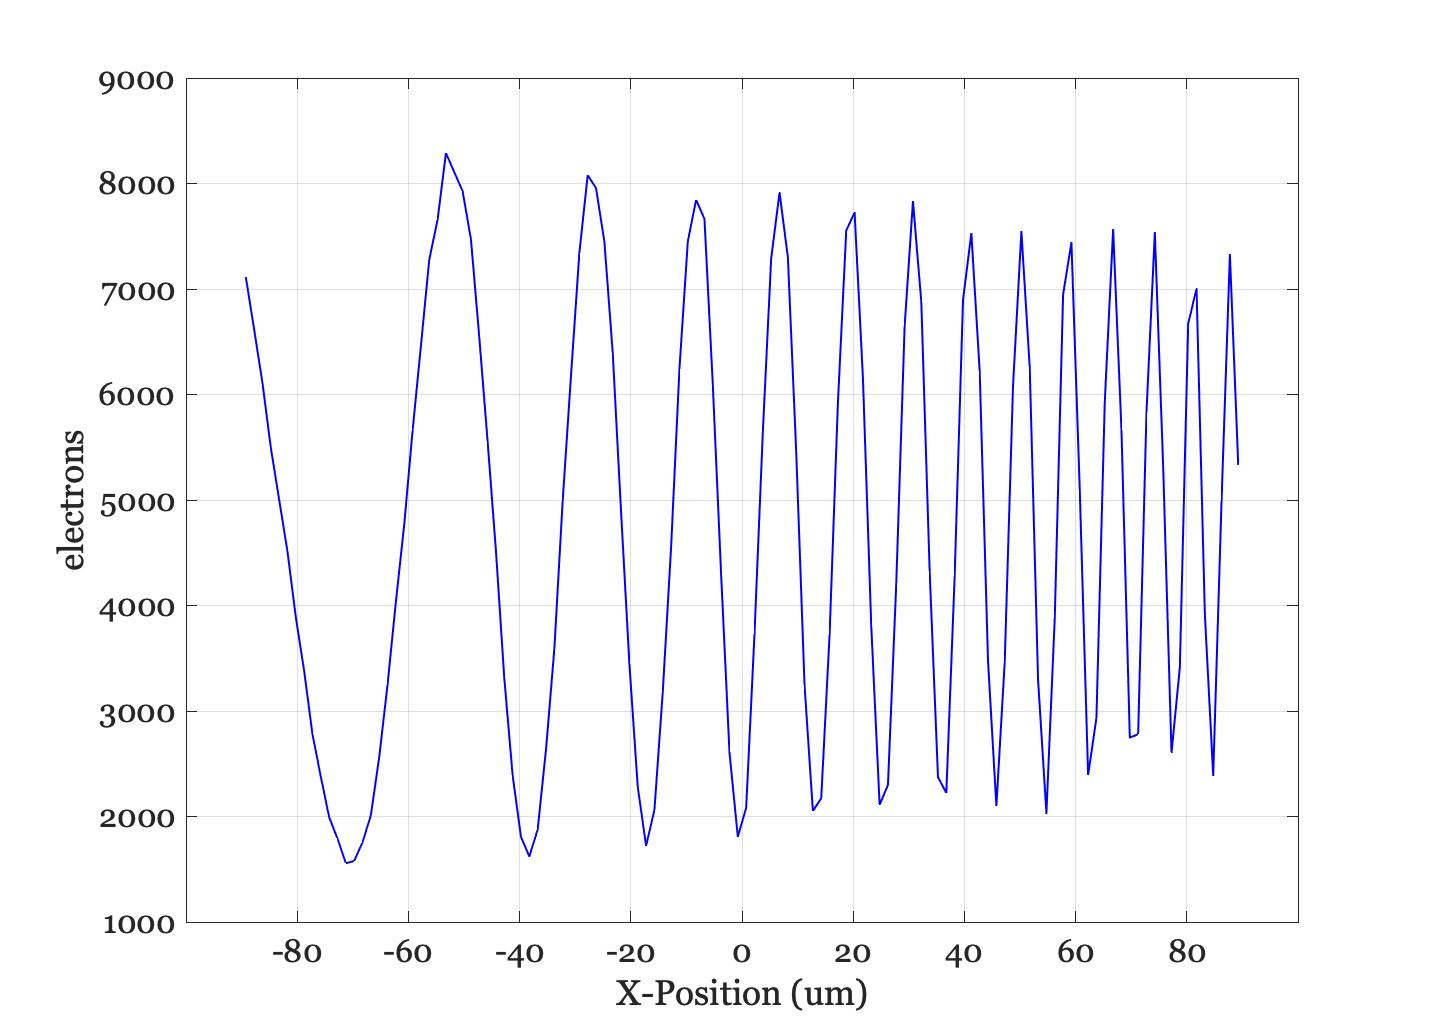


sensorPlot(sensor,'electrons hline',[5 1]);

## Make the sensor pixel under-sample by creating a large pixel.

Now, notice the aliased signal on the right.  The scene and oi are high spatial frequency, but the sensor capture appears to be low spatial frequency.

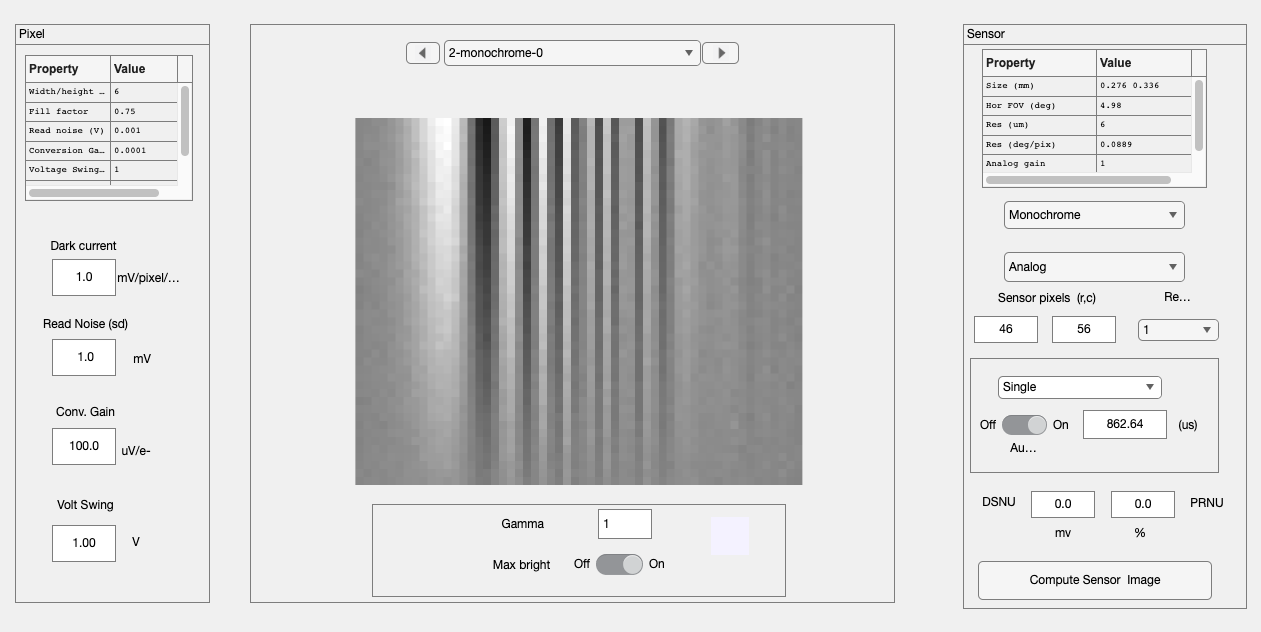

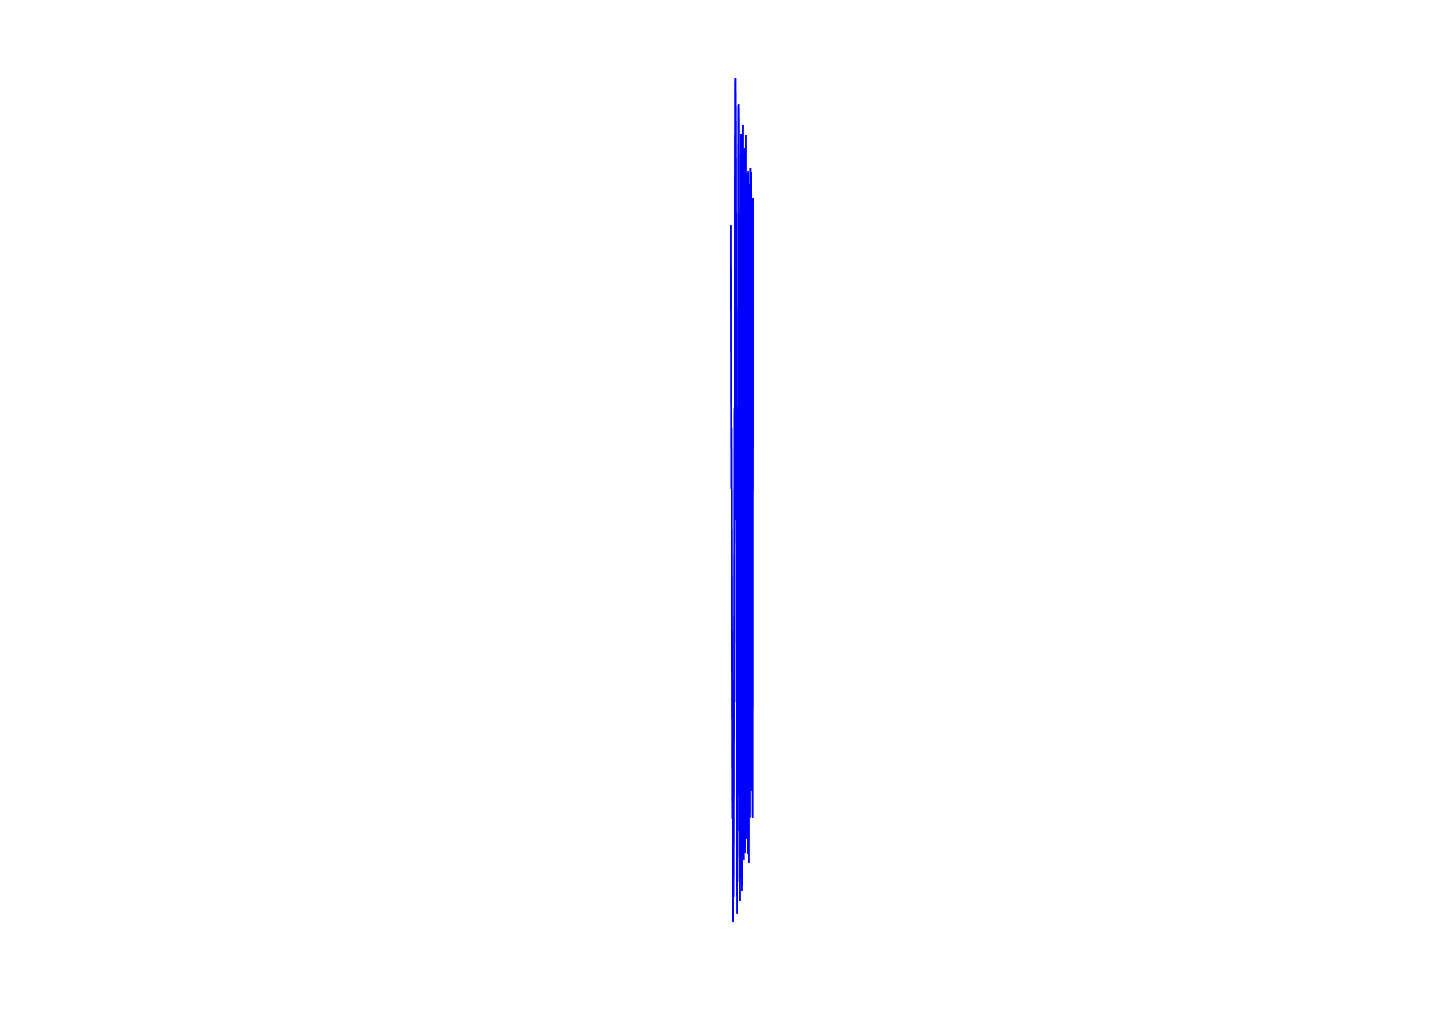

sensor = sensorSet(sensor,'pixel size constant fill factor',6e-6);
sensor = sensorSetSizeToFOV(sensor,fov,oi);
sensor = sensorCompute(sensor,oi);
sensorWindow(sensor);

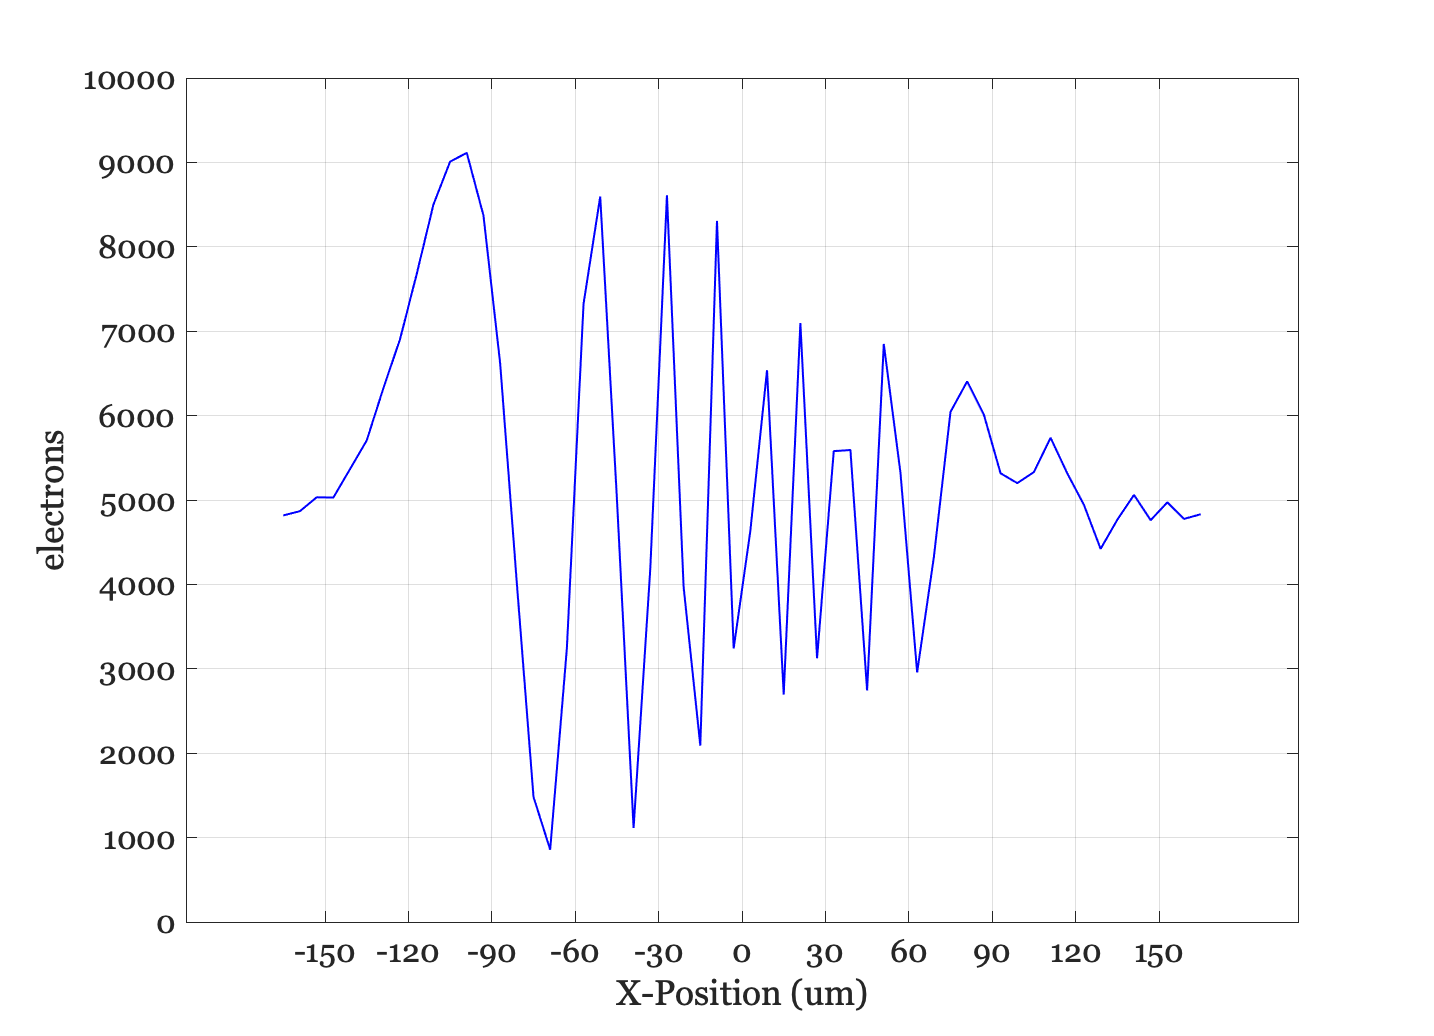


sensorPlot(sensor,'electrons hline',[5 1]);

## Now, protect from aliasing by using a blurry lens

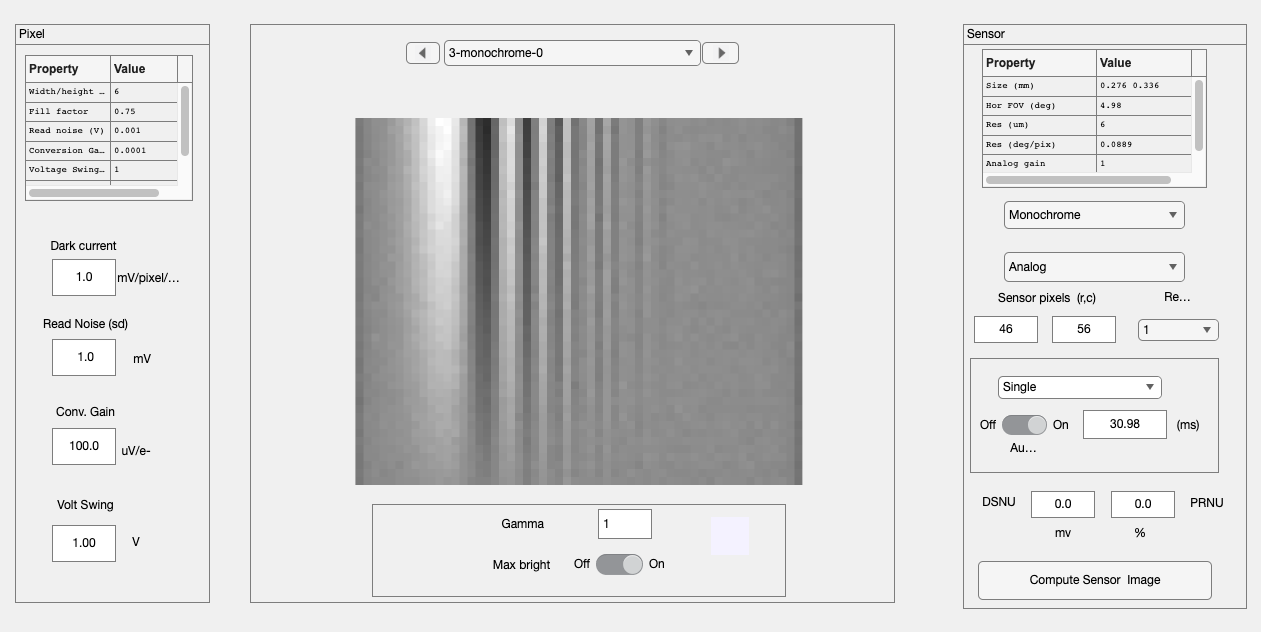

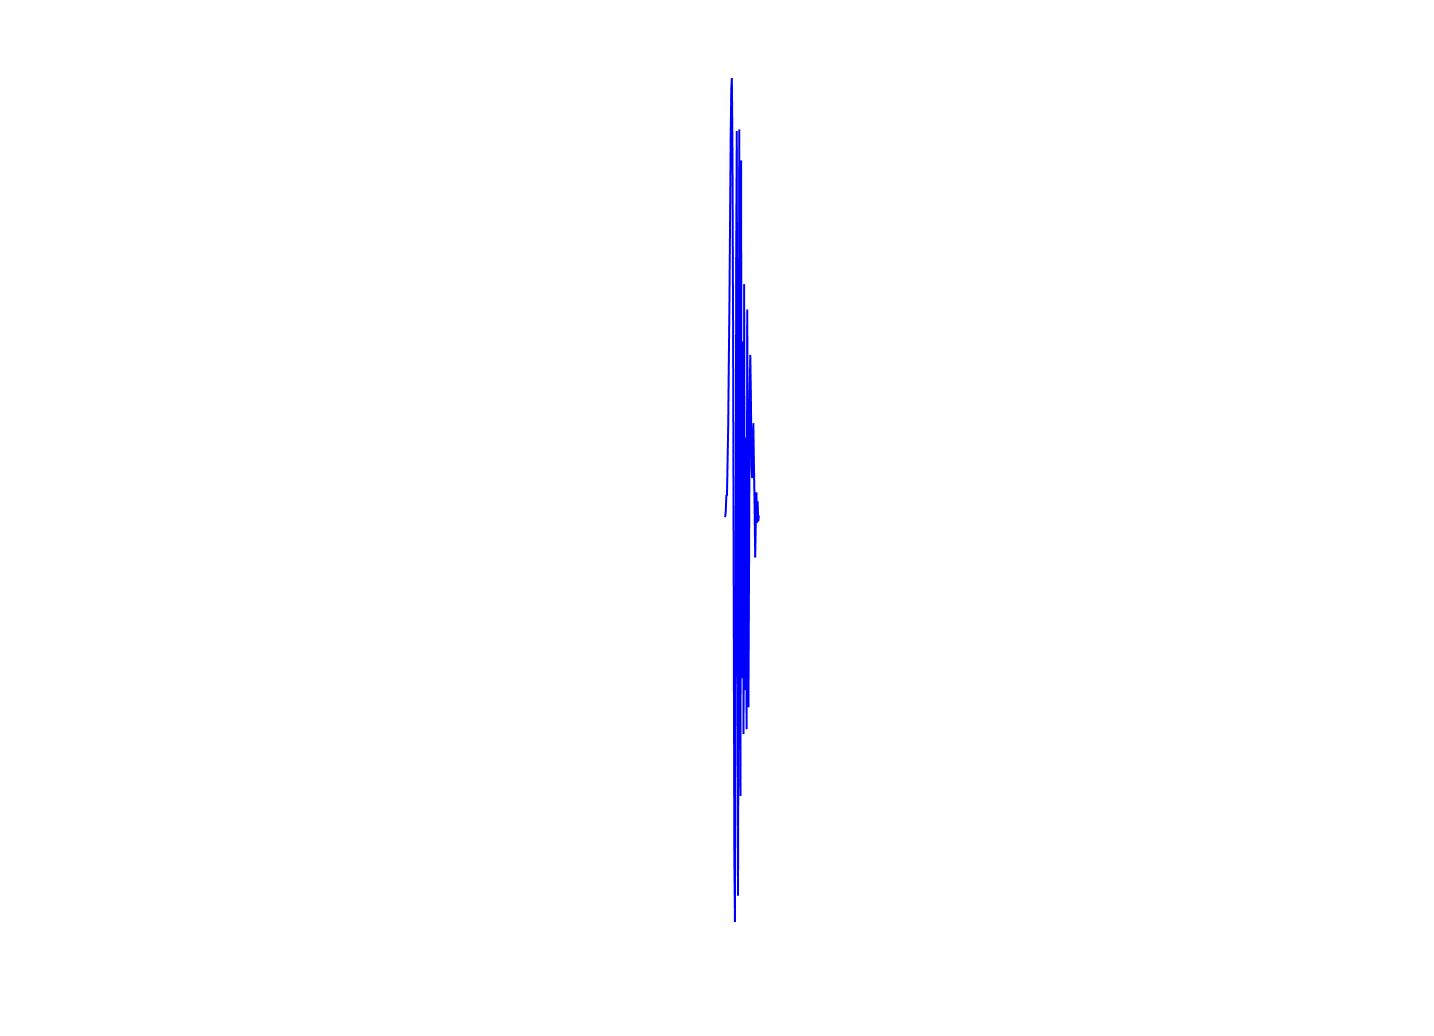

oi = oiSet(oi,'optics fnumber', 12);
oi = oiCompute(oi,scene);
sensor = sensorCompute(sensor,oi);
sensorWindow(sensor);

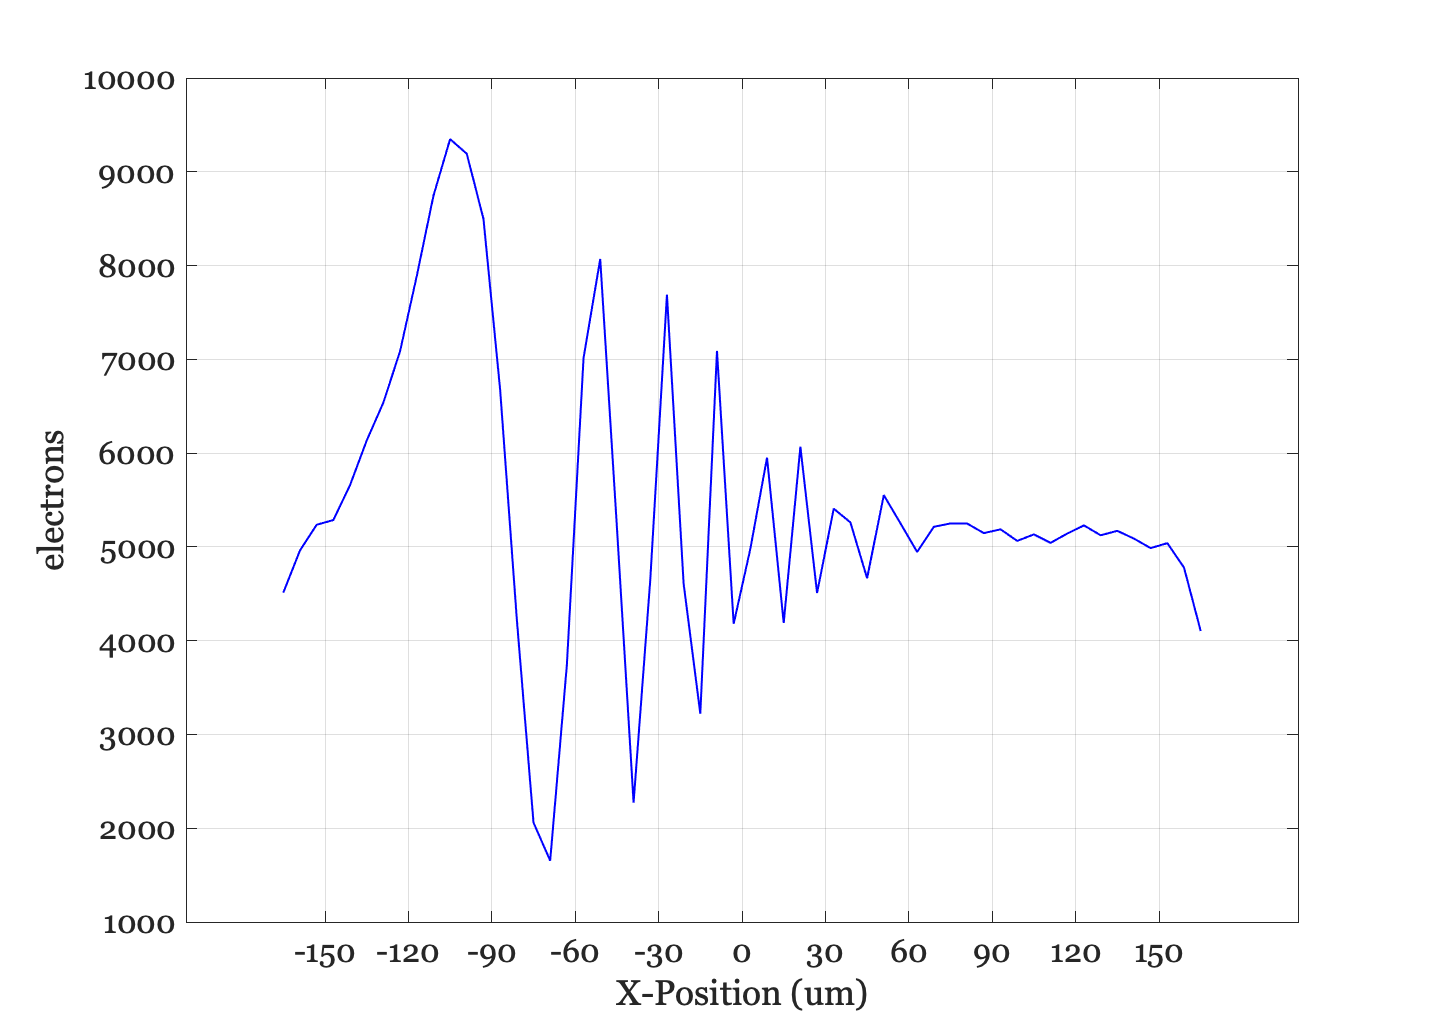

ans = struct with fields:
     pixPos: [-165.0000 -159.0000 -153.0000 -147.0000 -141 -135.0000 -129.0000 -123.0000 -117.0000 -111.0000 -105.0000 -99.0000 -93.0000 -87.0000 -81.0000 -75 -69.0000 -63.0000 -57.0000 -51.0000 -45.0000 -39.0000 -33 -27.0000 -21.0000 -15.0000 … ]
    pixData: [4512 4962 5236 5286 5658 6134 6539 7086 7887 8743 9348 9192 8498 6676 4228 2060 1654 3740 7013 8070 5212 2273 4647 7689 4608 3222 7089 4180 4979 5951 4189 6068 4509 5407 5261 4666 5552 5251 4946 5214 5250 5249 5147 5187 5064 5133 5043 … ]



sensorPlot(sensor,'electrons hline',[5 1])

## This is what aliasing looks like for the slanted bar target

This is why people sometimes say 'aliasing' creates 'jaggies'

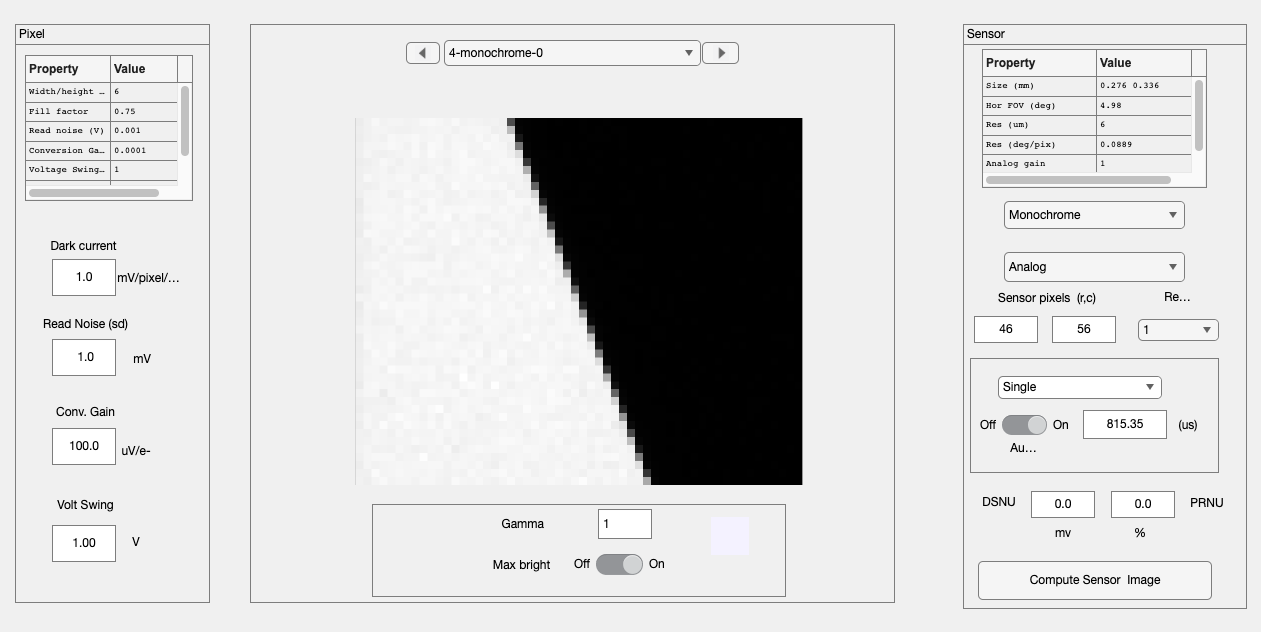

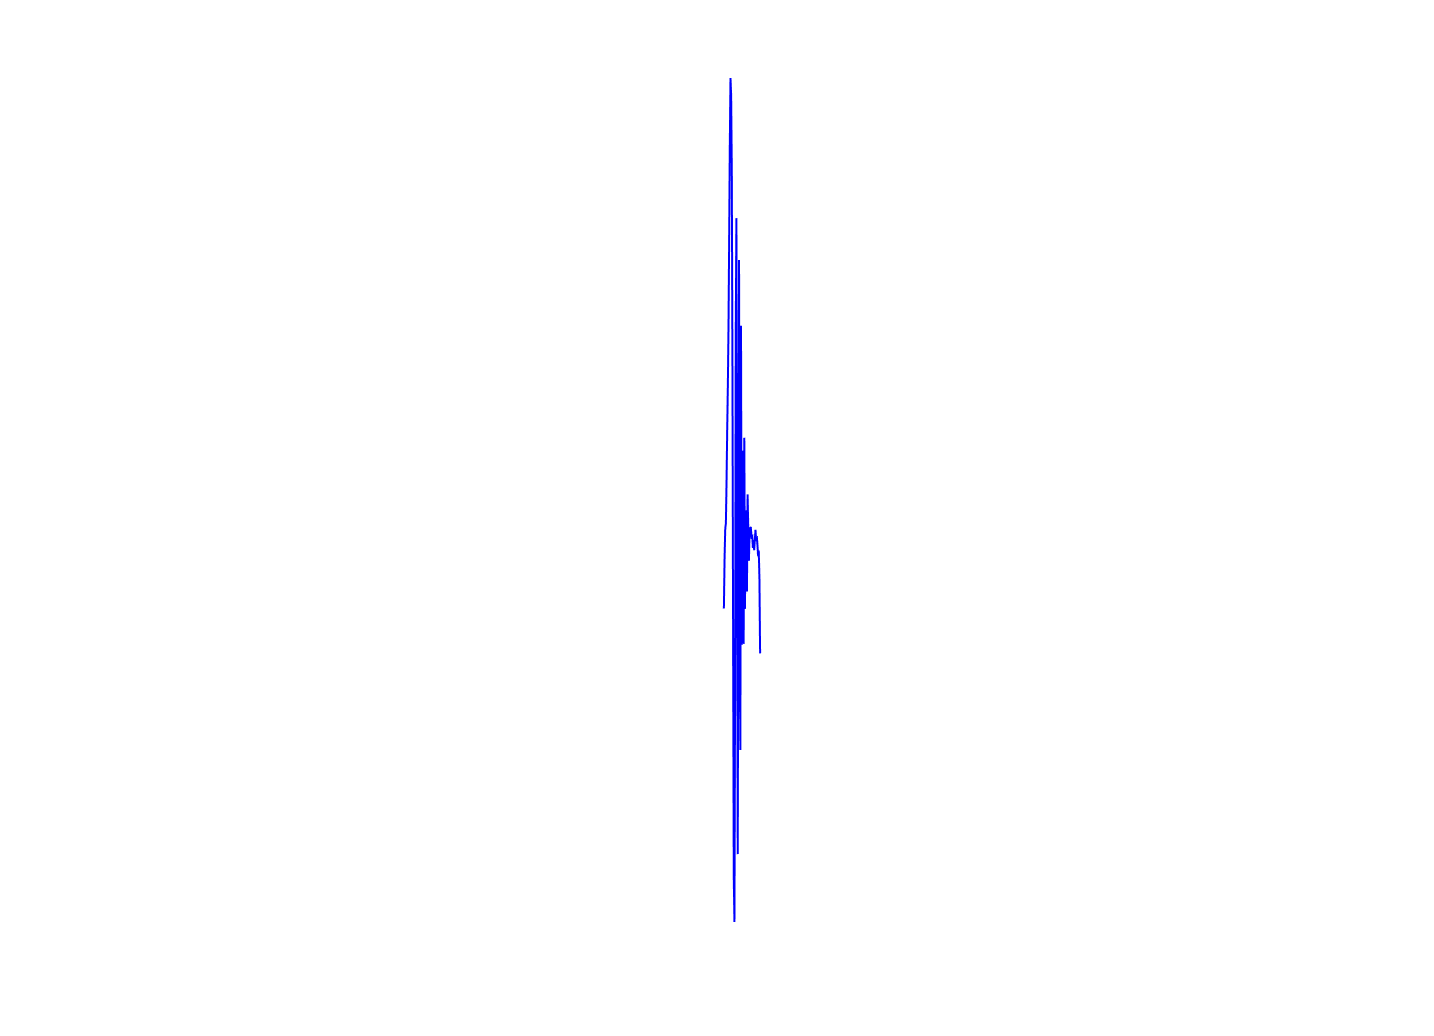

scene = sceneCreate('slanted bar',1024);
scene = sceneSet(scene,'fov',fov);

oi = oiSet(oi,'optics fnumber', 2);
sensor = sensorSet(sensor,'pixel size constant fill factor',6e-6);
sensor = sensorSetSizeToFOV(sensor,fov,oi);
oi = oiCompute(oi,scene);
sensor = sensorCompute(sensor,oi);
sensorWindow(sensor);

## If we protect against aliasing

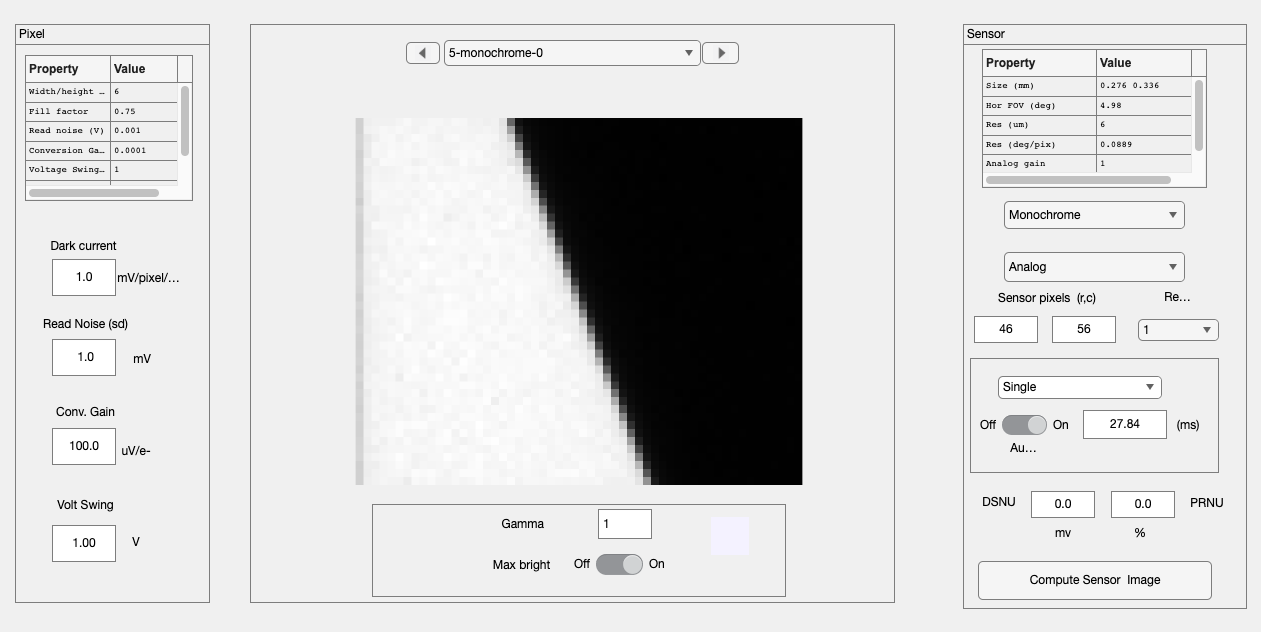

oi = oiSet(oi,'optics fnumber', 12);
oi = oiCompute(oi,scene);
sensor = sensorCompute(sensor,oi);
sensorWindow(sensor);